# Delta Modulator

## Delta Modulation written By Debagnik Kar 1804373

clc
close all
clear all

Taking User Inputs

am = input('Enter the value of amplitude:  ')

am = 50

fm = input('Enter the value of frequency:  ')

fm = 5


fs = input('Enter sampling Frequency:  ')

fs = 500


t = 0:1/fs:(2-(1/fs))

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


Message signal (Triangle wave)

w = 2*pi*fm

w = 31.4159

x = am*sawtooth(w*t,0.5)

x =          0    2.0000    4.0000    6.0000    8.0000   10.0000   12.0000   14.0000   16.0000   18.0000   20.0000   22.0000   24.0000   26.0000   28.0000   30.0000   32.0000   34.0000   36.0000   38.0000   40.0000   42.0000   44.0000   46.0000   48.0000   50.0000   52.0000   54.0000   56.0000   58.0000   60.0000   62.0000   64.0000   66.0000   68.0000   70.0000   72.0000   74.0000   76.0000   78.0000   80.0000   82.0000   84.0000   86.0000   88.0000   90.0000   92.0000   94.0000   96.0000   98.0000


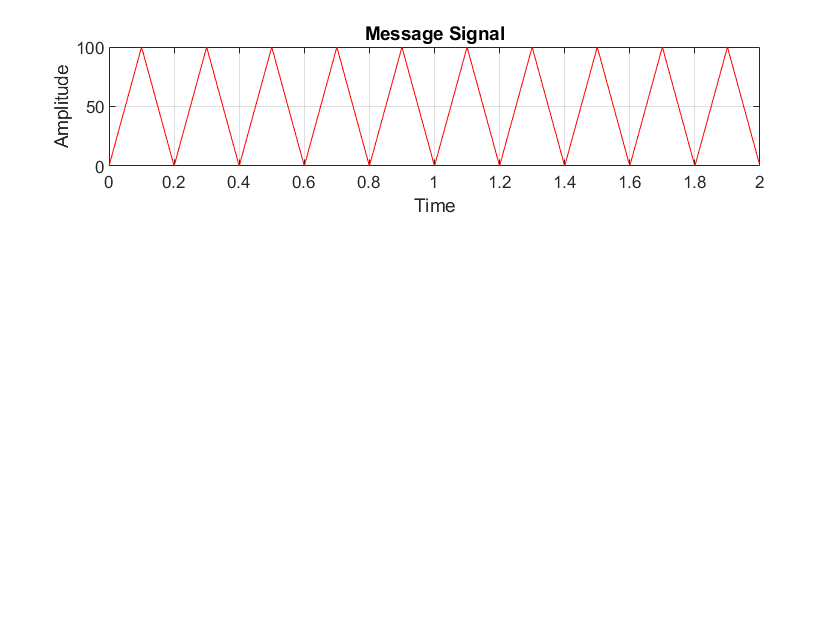


subplot 311
plot(t,x,'r')
grid on
ylabel('Amplitude')
xlabel('Time')
title('Message Signal')

Quantization of the signal

d = w/fs

d = 0.0628


for n = 1:length(x)
    if n==1
        e(n) = x(n)
        eq(n) = d*sign(e(n))
        xq(n) = eq(n)
    else
        e(n) = x(n)-xq(n-1)
        eq(n) = d*sign(e(n))
        xq(n) = eq(n)+xq(n-1)
    end
end

e = 0

eq = 0

xq = 0

e =      0     2


eq =          0    0.0628


xq =          0    0.0628


e =          0    2.0000    3.9372


eq =          0    0.0628    0.0628


xq =          0    0.0628    0.1257


e =          0    2.0000    3.9372    5.8743


eq =          0    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885


e =          0    2.0000    3.9372    5.8743    7.8115


eq =          0    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221


e =          0    2.0000    3.9372    5.8743    7.8115    9.7487   11.6858   13.6230   15.5602   17.4973   19.4345   21.3717   23.3088   25.2460   27.1832   29.1204   31.0575   32.9947   34.9319   36.8690   38.8062   40.7434   42.6805   44.6177   46.5549   48.4920   50.4292   52.3664   54.3035   56.2407


eq =          0    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628    0.0628


xq =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221



subplot 312
stairs(t,xq,'b')
hold on
plot(t,x,'y')
hold off
grid on
ylabel('Amplitude')
xlabel('Time')
title('Quantized Signal')

Delta Modulation

for i = 1:length(x)
    if e(i)>0
        delta(i) = 1
    else
        delta(i) = 0
    end
end

subplot 313
stairs(t,delta,'g')
grid on
axis([0 2 -1 2])
xlabel('time')
ylabel('amplitude')
title('Delta modulated signal')